clc
clear all
close all

% --- Data In ---
A = 1; 
f = 3000;
cantper = 2;
phi = 0;
compFrecuencia = 10;

% --- Process ---
t = linspace(0, cantper/f,500);
sinusoidal = A * sin(2 * pi * f * t + phi);

% Cuadrada 
cuadrado = 0;
for n = 1:2: (2 * compFrecuencia - 1)
	cuadrado = cuadrado + (A/n) * sin(2 * pi * n * f * t);
end

% Triangular
triangular = 0;
for n = 1:2: (2 * compFrecuencia - 1)
	triangular = triangular + (A/n^2) * cos(2 * pi * n * f * t);
end

% Dientes de sierra
dsierra = 0;
for n = 1: compFrecuencia
	if (mod(n,2) == 0)
		signo = -1
	else 
		signo = 1
	end
	dsierra = dsierra + signo * (A/n) * sin(2 * pi * n * f * t);
end

signo = 1

signo = -1

signo = 1

signo = -1

signo = 1

signo = -1

signo = 1

signo = -1

signo = 1

signo = -1

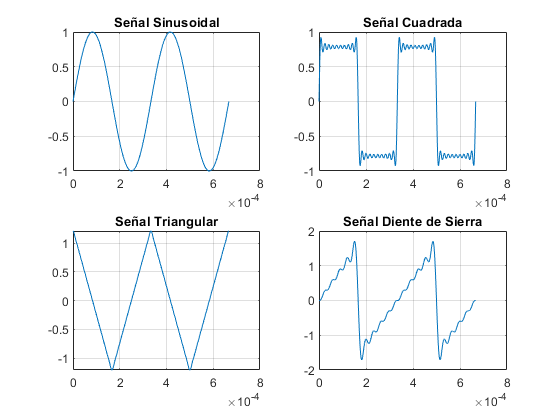


% Output
figure(1)
subplot(2,2,1), plot(t, sinusoidal), title('Señal Sinusoidal'), grid on

subplot(2,2,2), plot(t, cuadrado), title('Señal Cuadrada'), grid on

subplot(2,2,3), plot(t, triangular), title('Señal Triangular'), grid on

subplot(2,2,4), plot(t, dsierra), title('Señal Diente de Sierra'), grid on